frameSize = 128;
inFs      = 44100;
outFs     = 96000;
source = dsp.Chirp(InitialFrequency=0,TargetFrequency=22e3, ...
    SweepTime=8,TargetTime=8,SampleRate=inFs, ...
    SamplesPerFrame=frameSize,Type="Quadratic");
SpectrumAnalyzerIn = spectrumAnalyzer( ...
    SampleRate=inFs, ...
    Method="welch", ...
    AveragingMethod="exponential", ...
    ForgettingFactor=1e-7, ...
    ViewType="spectrum-and-spectrogram", ...
    TimeSpanSource="property",TimeSpan=8, ...
    Window="kaiser",SidelobeAttenuation=220, ...
    YLimits=[-250, 50],ColorLimits=[-150, 20], ...
    PlotAsTwoSidedSpectrum=false);
SpectrumAnalyzerOut = spectrumAnalyzer( ...
    SampleRate=outFs, ...
    Method="welch", ...
    AveragingMethod="exponential", ...
    ForgettingFactor=1e-7, ...
    ViewType="spectrum-and-spectrogram", ...
    TimeSpanSource="property",TimeSpan=8, ...
    Window="kaiser",SidelobeAttenuation=220, ...
    YLimits=[-250, 50],ColorLimits=[-150, 20], ...
    PlotAsTwoSidedSpectrum=false);
NFrames = 8*inFs/frameSize;

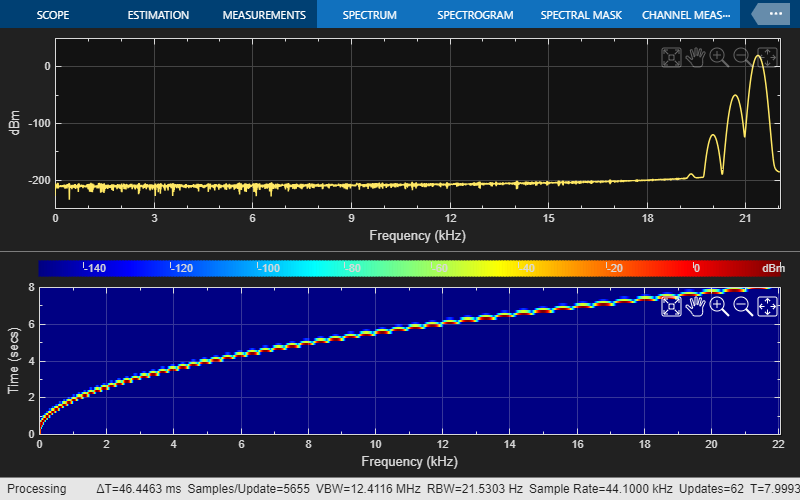

iabuf = dsp.AsyncBuffer(inFs * 10);
for k = 1:NFrames
    sigIn = source();          % Source
    SpectrumAnalyzerIn(sigIn); % Spectrogram
    write(iabuf, sigIn);
end

[soundin, ~] = read(iabuf, iabuf.NumUnreadSamples);
release(iabuf);

sound(soundin * 0.25, inFs);

% fast 2x interpolator with less image rejection
N     = 191;     % Order
Fpass = 0.48;    % Passband Frequency
Fstop = 0.55;    % Stopband Frequency

h = fdesign.interpolator(2, 'Lowpass', 'n,fp,fst', N, Fpass, Fstop);

Hint2fast = design(h, 'equiripple', ...
    'Wstop', 10000, ...
    'StopbandShape', 'flat', ...
    'SystemObject', true);

set(Hint2fast, ...
    'FullPrecisionOverride', false, ...
    'CoefficientsDataType', 'Custom', ...
    'CustomCoefficientsDataType', numerictype([],32,31), ...
    'ProductDataType', 'Custom', ...
    'CustomProductDataType', numerictype([],64,62), ...
    'AccumulatorDataType', 'Custom', ...
    'CustomAccumulatorDataType', numerictype([],64,62), ...
    'OutputDataType', 'Same as input');

% high-quality 2x interpolator with good image rejection (but slower with more delay)
N     = 511;     % Order
Fpass = 0.48;    % Passband Frequency
Fstop = 0.505;   % Stopband Frequency

h = fdesign.interpolator(2, 'Lowpass', 'n,fp,fst', N, Fpass, Fstop);

Hint2hq = design(h, 'equiripple', ...
    'Wstop', 20000, ...
    'StopbandShape', 'flat', ...
    'SystemObject', true);

set(Hint2hq, ...
    'FullPrecisionOverride', false, ...
    'CoefficientsDataType', 'Custom', ...
    'CustomCoefficientsDataType', numerictype([],32,31), ...
    'ProductDataType', 'Custom', ...
    'CustomProductDataType', numerictype([],64,62), ...
    'AccumulatorDataType', 'Custom', ...
    'CustomAccumulatorDataType', numerictype([],64,62), ...
    'OutputDataType', 'Same as input');

% fractional SRC for 160/147 (or 160/294) ratio conversion
N     = 2559;     % Order
Fpass = 0.00325;  % Passband Frequency
Fstop = 0.00875;  % Stopband Frequency
Astop = 155;      % Stopband Attenuation (dB)

h = fdesign.rsrc(160, 147, 'Lowpass', 'n,fp,fst,ast', N, Fpass, Fstop, Astop);

Hfrac = design(h, 'equiripple', ...
    'SystemObject', true);

set(Hfrac, ...
    'FullPrecisionOverride', false, ...
    'CoefficientsDataType', 'Custom', ...
    'CustomCoefficientsDataType', numerictype([],32,31), ...
    'ProductDataType', 'Custom', ...
    'CustomProductDataType', numerictype([],32,30), ...
    'AccumulatorDataType', 'Custom', ...
    'CustomAccumulatorDataType', numerictype([],32,30), ...
    'OutputDataType', 'Same as input');%, ...
    %'DecimationFactor', 294);


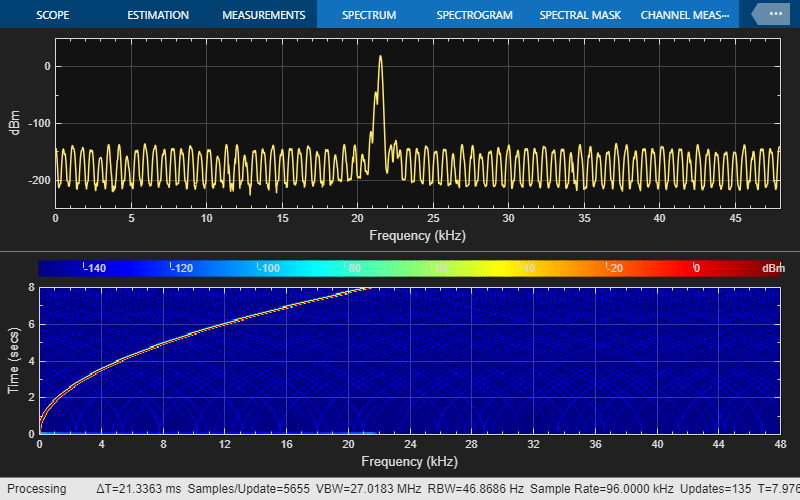

buff = dsp.AsyncBuffer;
obuf = dsp.AsyncBuffer(outFs * 10);
srcFrameSize = 160;
for k = 1:NFrames
    sigIn = Hint2hq(source() / 2);     % Get chirp and interpolate 2x
    over = write(buff,sigIn);      % Buffer data
    while buff.NumUnreadSamples >= srcFrameSize
        [sigInbuffered,~] = read(buff,srcFrameSize);
        sigOut = Hfrac(sigInbuffered / 16) * 16 * 2; % Convert sample-rate
        SpectrumAnalyzerOut(sigOut);   % View spectrum of converted signal
        write(obuf,sigOut);
    end
end

[soundout,~] = read(obuf, obuf.NumUnreadSamples);
release(obuf);

sound(soundout * .25, outFs)

% more ideal direct SRC but with wayy more coefficients
BW = 2 * 21e3;
SRC = dsp.SampleRateConverter(Bandwidth=BW, ...
    InputSampleRate=inFs,OutputSampleRate=outFs, ...
    StopbandAttenuation=130);
info(SRC)
[Hsrc,f] = freqz(SRC,0:10:25e3);
plot(f,20*log10(abs(Hsrc)/norm(Hsrc,inf)));
xlabel("Frequency (Hz)")
ylabel("Magnitude (dB)")
axis([0 25e3 -250 5])

buff = dsp.AsyncBuffer;
srcFrameSize = 160;
for k = 1:NFrames
    sigIn = source();              % Generate chirp
    over = write(buff,sigIn);      % Buffer data
    if buff.NumUnreadSamples >= srcFrameSize
        [sigInbuffered,under] = read(buff,srcFrameSize);
        sigOut = SRC(sigInbuffered); % Convert sample-rate
        SpectrumAnalyzerOut(sigOut);   % View spectrum of converted signal
    end
end

coeffs(SRC).Stage1

release(source);
release(SpectrumAnalyzerOut);
release(buff);
release(SpectrumAnalyzerIn);